% Task1_FDM_1D_Aluminum_corrected.m
% Corrected Task 1 only: 1D acoustic wave on aluminum rod
% Source injected as prescribed displacement (so recorded traces keep source shape)
% Units: SI
clear
%% Material & discretization (from lab)
E   = 70e9;      % Young's modulus [Pa] (aluminum)
rho = 2700;      % density [kg/m^3]
c   = sqrt(E/rho); % wave speed [m/s]
fprintf('Aluminum wave speed c = %.1f m/s\n', c);

Aluminum wave speed c = 5091.8 m/s



dx = 1e-3;       % spatial step 1 mm
dt = 0.12e-6;    % time step 0.12 microsecond
r = c*dt/dx;
fprintf('CFL r = %.4f\n', r);

CFL r = 0.6110


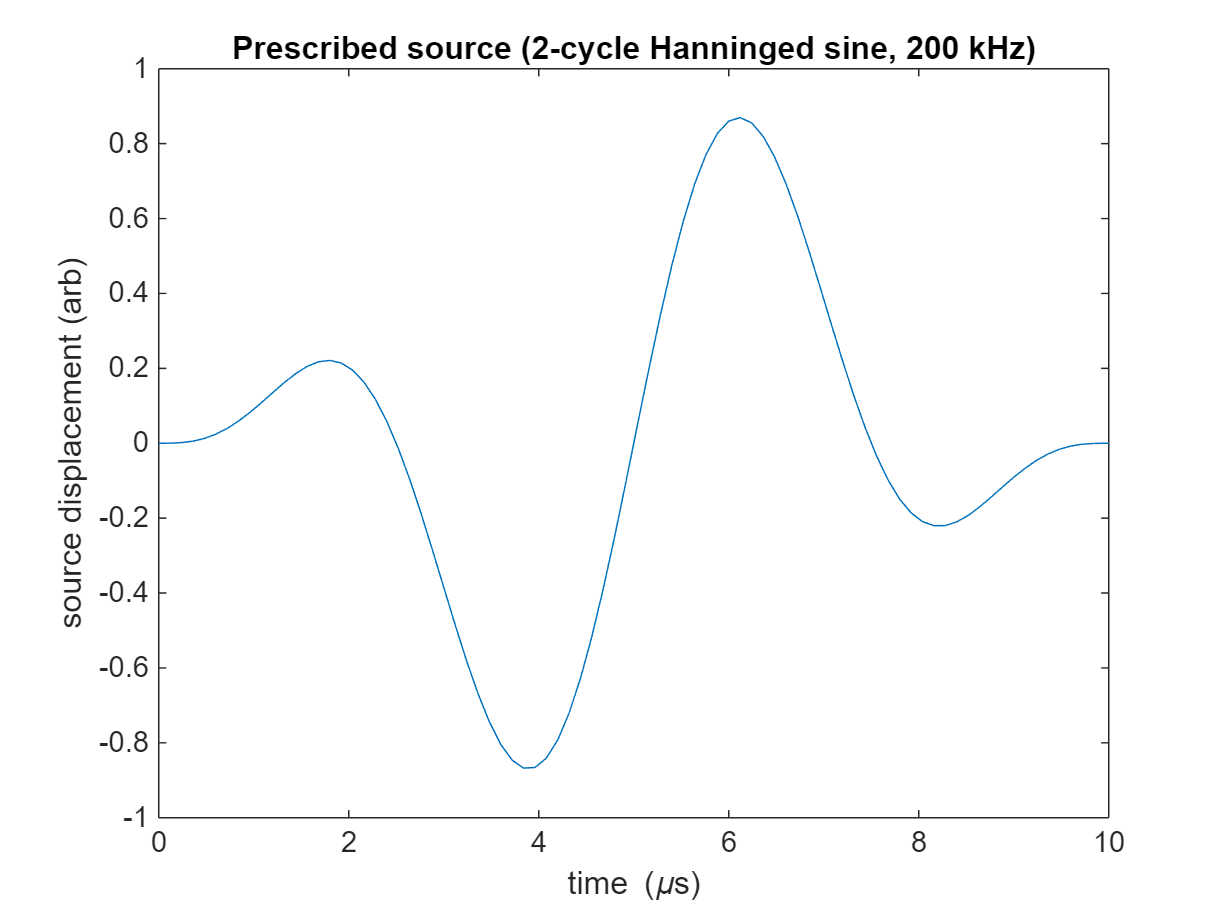


%% Domain & time
L = 0.5;                   % rod length [m] (600 mm)
x = 0:dx:L;
Nx = numel(x);

tmax = 150e-6;             % total simulation time (s)
nt = ceil(tmax/dt);
time = (0:nt-1)*dt;

%% Source (200 kHz, 2 cycles, Hanning envelope)
f0 = 200e3; ncycles = 2;
Tcycle = 1/f0;
Tsrc = ncycles * Tcycle;
t_src = (0:nt-1)*dt;                % time vector for source (longer than needed, ok)
src_envelope = zeros(size(t_src));
idx_src = (t_src >= 0) & (t_src <= Tsrc);
src_envelope(idx_src) = 0.5*(1 - cos(2*pi*t_src(idx_src)/Tsrc)); % Hanning over [0,Tsrc]
src_signal = sin(2*pi*f0*t_src) .* src_envelope;

% quick plot of the source to confirm shape
figure('Name','Input source'); plot(t_src*1e6, src_signal); xlabel('time (\mus)'); ylabel('source displacement (arb)'); title('Prescribed source (2-cycle Hanninged sine, 200 kHz)');
xlim([0 10])

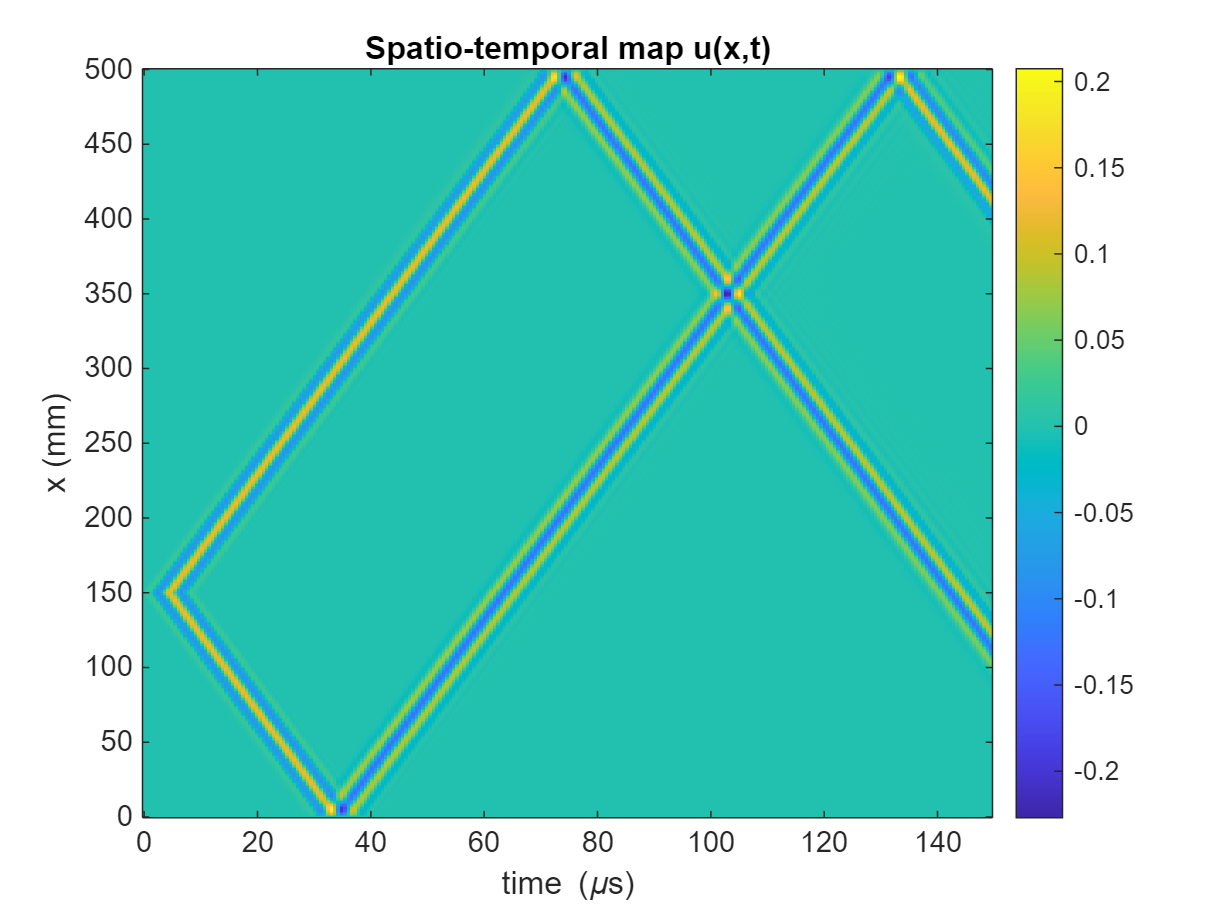



%% Source location
xsrc = 0.150;                         % 150 mm
[~, isrc] = min(abs(x - xsrc));

%% Initialize fields (time levels)
u_prev = zeros(Nx,1);   % u^{n-1}
u_curr = zeros(Nx,1);   % u^{n}
u_next = zeros(Nx,1);   % u^{n+1}

% Set initial source displacement at t=0 (u_curr) and t=-dt (u_prev) for smooth start
u_curr(isrc) = src_signal(1);
% For u_prev, assume source before t=0 is 0 (or equal to src at negative time if desired)
u_prev(isrc) = 0;  % could set to src_signal(1-dt) if defined; zero is acceptable here

%% Measurement points (to compare traces with source)
x_meas1 = 0.050; [~, i_meas1] = min(abs(x - x_meas1)); % 50 mm
x_meas2 = 0.300; [~, i_meas2] = min(abs(x - x_meas2)); % 300 mm
trace1 = zeros(nt,1);
trace2 = zeros(nt,1);

%% Precompute
r2 = (c*dt/dx)^2;

%% Time-stepping (explicit central-difference)
% We'll store a spatio-temporal matrix at regular snapshot intervals for plotting
Ksnap = max(1, floor(nt/250));
nSnaps = ceil(nt / Ksnap);
stamps = zeros(Nx, nSnaps);
snapIdx = 1;


%------------------------------------------------------------------------------%
%--- 1) Precompute discrete acceleration of the 2-cycle Hann signal
%------------------------------------------------------------------------------%
src_acc = zeros(size(src_signal));
% central second difference for 2 ≤ n ≤ nt-1
src_acc(2:end-1) = ( ...
     src_signal(3:end) ...
   - 2*src_signal(2:end-1) ...
   + src_signal(1:end-2) ...
) / dt^2;
% set edges to zero (no injection at n=1 or n=nt)
src_acc(1)   = 0;
src_acc(end) = 0;

% Main loop
for n = 1:nt
  % time-stepping interior
  for i = 2:Nx-1
    u_next(i) = 2*u_curr(i) - u_prev(i) ...
               + r2*(u_curr(i+1) - 2*u_curr(i) + u_curr(i-1));
  end

  % ----------- ADD: exact acceleration forcing at source -------------
  u_next(isrc) = u_next(isrc) + src_acc(n)*dt^2;

  % Dirichlet at ends
  u_next(1)  = 0;
  u_next(Nx) = 0;

  % record
  trace1(n) = u_next(i_meas1);
  trace2(n) = u_next(i_meas2);
  if mod(n,Ksnap)==0
    stamps(:,snapIdx) = u_next; 
    snapIdx = snapIdx + 1;
  end

  % shift
  u_prev = u_curr;
  u_curr = u_next;
end

%% Plot spatio-temporal map and traces and compare to source (shifted)
figure('Name','Task1: Spatio-temporal & traces','Units','normalized','Position',[0.05 0.05 0.9 0.8]);

figure
time_snaps = (0:(size(stamps,2)-1))*Ksnap*dt;
imagesc(time_snaps*1e6, x*1e3, stamps); axis xy;
xlabel('time (\mus)'); ylabel('x (mm)');
title('Spatio-temporal map u(x,t)'); colorbar;

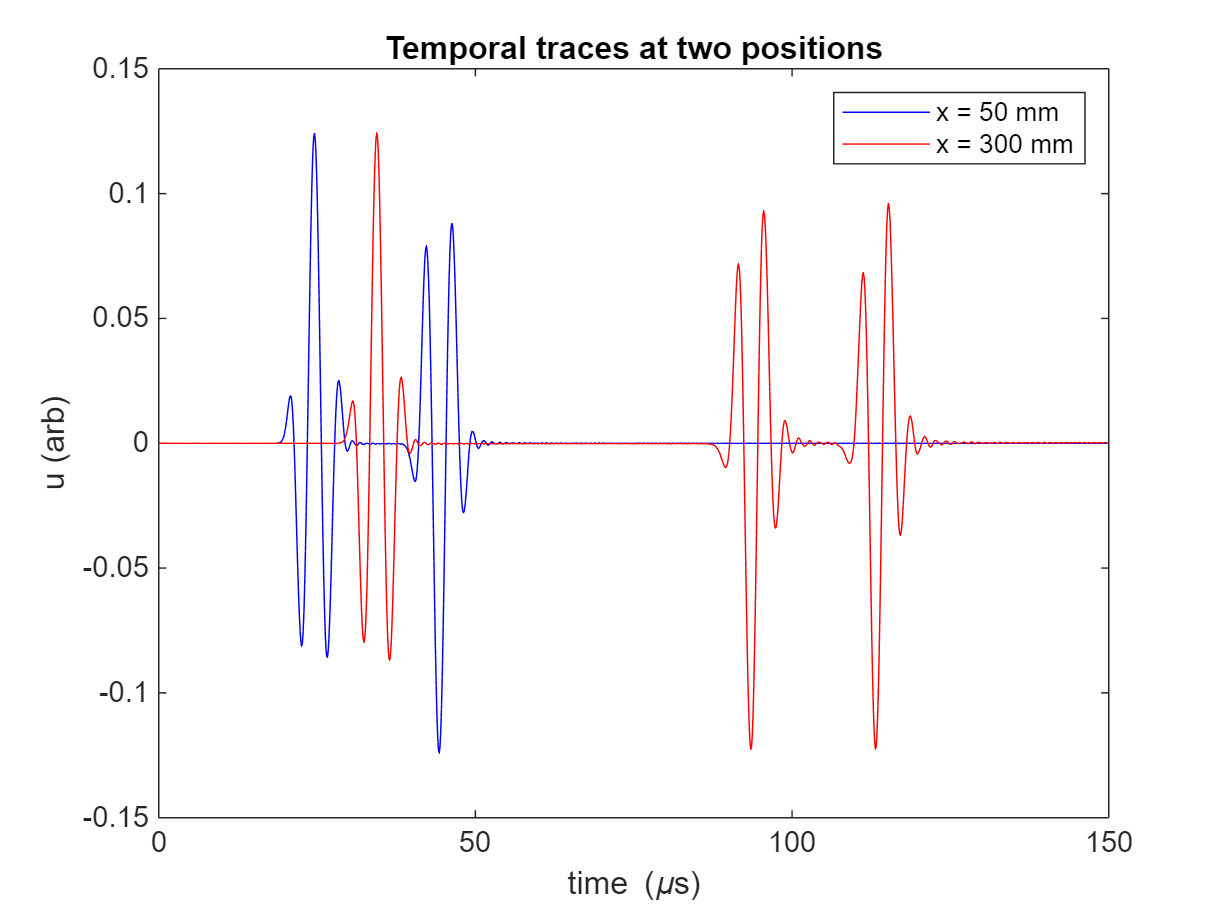


figure
plot(time*1e6, trace1, 'b'); hold on;
plot(time*1e6, trace2, 'r'); xlabel('time (\mus)'); ylabel('u (arb)');
legend(sprintf('x = %.0f mm', x_meas1*1e3), sprintf('x = %.0f mm', x_meas2*1e3));
title('Temporal traces at two positions');

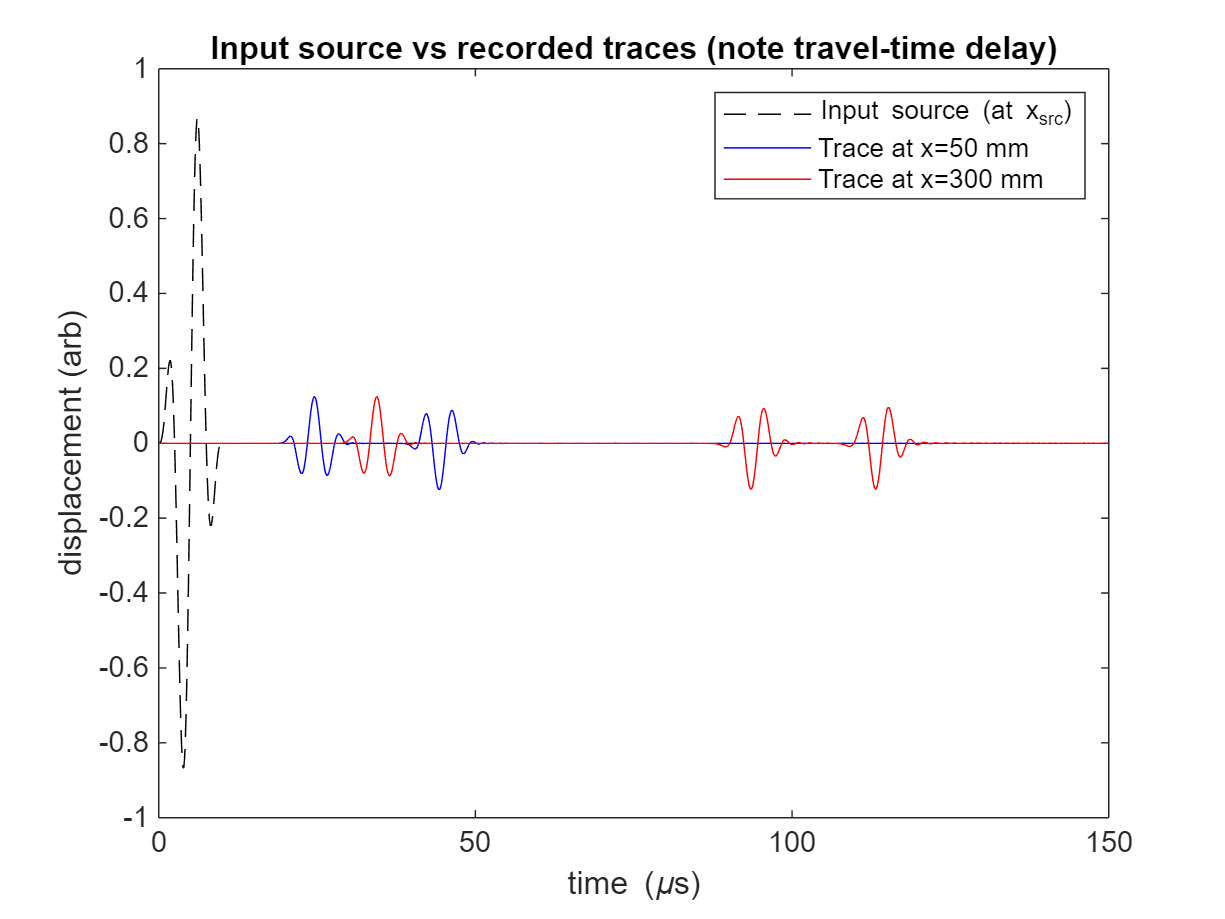


% Compare trace at nearest sensor with the input source (shifted by travel time)
figure
plot(time*1e6, src_signal, 'k--', 'DisplayName','Input source (at x_{src})'); hold on;
plot(time*1e6, trace1, 'b', 'DisplayName', sprintf('Trace at x=%.0f mm', x_meas1*1e3));
plot(time*1e6, trace2, 'r', 'DisplayName', sprintf('Trace at x=%.0f mm', x_meas2*1e3));
xlabel('time (\mus)'); ylabel('displacement (arb)');
legend; title('Input source vs recorded traces (note travel-time delay)');


%% Estimate wave speed from arrival times
% Find first strong peak in each trace (use absolute)
minPeakHeight1 = 0.25 * max(abs(trace1));
minPeakHeight2 = 0.25 * max(abs(trace2));
[pks1, locs1] = findpeaks(abs(trace1), 'MinPeakHeight', max(minPeakHeight1,eps), 'MinPeakDistance', 3);
[pks2, locs2] = findpeaks(abs(trace2), 'MinPeakHeight', max(minPeakHeight2,eps), 'MinPeakDistance', 3);
if ~isempty(locs1) && ~isempty(locs2)
    tA = locs1(1)*dt;
    tB = locs2(1)*dt;
    est_c = abs(x(i_meas2)-x(i_meas1))/(tB - tA);
    fprintf('Estimated wave speed (Task1) = %.1f m/s (theoretical c = %.1f m/s)\n', est_c, c);
else
    fprintf('Could not reliably pick arrival peaks for speed estimation.\n');
end

Estimated wave speed (Task1) = 25406.5 m/s (theoretical c = 5091.8 m/s)



disp('Task 1 completed (corrected).')

Task 1 completed (corrected).
